# `Numerical Derivatives Group Assignment`

#### `Bethany Wu & Alex Stapely`

## `Problem 1: Finite Differences`

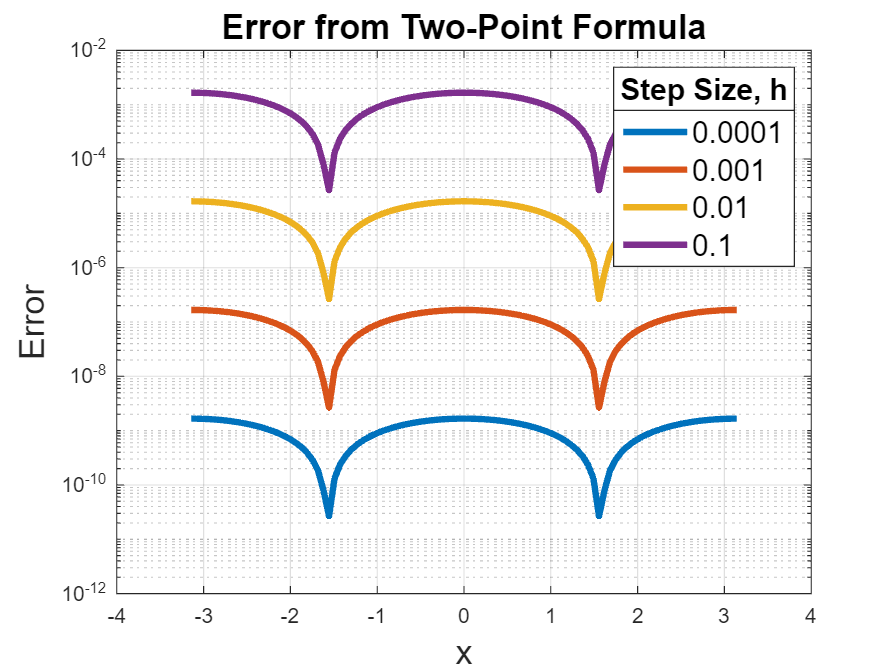

syms x0 h0
x = linspace(-pi,pi,100);
y = @sin;
dydx = @(x0,h0)  (y(x0+h0)-y(x0-h0))/(2*h0);

hs = [0.0001 0.001 0.01 0.1];
figure();
for h = hs
    yp = dydx(x,h);
    semilogy(x,abs(yp-cos(x)),'LineWidth',3); hold on;
end
title('Error from Two-Point Formula','FontSize',16); xlabel('x','FontSize',16); ylabel('Error','FontSize',16);
leg = legend(string(hs),'FontSize',14); title(leg,'Step Size, h'); grid on; hold off;

`Looking at the error plot, as h is decreased by an order of magnitude, the overall error of the derivative using the two-point formula us decreased by TWO orders of magnitude! When h = 1e-4, the error is in the range 1e-11 to 1e-9.`

## `Problem 2: More sophisticated derivatives...`

### `Part (a)`

`Richardson extrapolation of the finite difference formulas: Alex`

%Example use of Richardson extrapolation
f=@(x) sin(x);
% x = Point(s) to evaluate at
x = pi;
% Step
h = 0.4;
% Order of extrapolation 
n = 4;
[result, der, h] = richardson(f,x,h,n);
% Prints Result
fprintf('According to the Richardson extrapolation method, the derivative is: %.9f\n', der);

According to the Richardson extrapolation method, the derivative is: -0.999999998


`AD using dual numbers:`

`Chebyshev methods:`

## `Part (b)`

% %Write a driver function that allows you to use a common interface to apply the methods 
% % you implemented in part (a) with an arbitrary function. 
% 
% % Set up arbitrary function and parameters
% f=@(x) sin(x);
% % x = Point(s) to evaluate at
% x = pi;
% % Step
% h = 0.4;
% % Order of extrapolation 
% n = 4;

% % Calling that function here
% compare(f,x,h,n)

## `Part (c)`

% sin(x) for 100 points between -pi and pi
f=@(x) sin(x);
xs = linspace(-pi,pi,100);
h = 0.4;
n = 4;
for i = 1:100
     x=xs(i);
     compare(f,x,h,n);
end

According to the Richardson extrapolation method, the derivative is: -1.0000
According to the Richardson extrapolation method, the derivative is: -0.9980
According to the Richardson extrapolation method, the derivative is: -0.9920
According to the Richardson extrapolation method, the derivative is: -0.9819
According to the Richardson extrapolation method, the derivative is: -0.9679
According to the Richardson extrapolation method, the derivative is: -0.9501
According to the Richardson extrapolation method, the derivative is: -0.9284
According to the Richardson extrapolation method, the derivative is: -0.9029
According to the Richardson extrapolation method, the derivative is: -0.8738
According to the Richardson extrapolation method, the derivative is: -0.8413
According to the Richardson extrapolation method, the derivative is: -0.8053
According to the Richardson extrapolation method, the derivative is: -0.7660
According to the Richardson extrapolation method, the derivative is: -0.7237

% sin(1/x) for 100 points between [-1,1]
f2=@(x) 1/sin(x);
xs2 = linspace(-1,1,100);
h2 = 0.4;
n2 = 4;
for i = 1:100
     x2=xs2(i);
     compare(f2,x2,h2,n2);
end

According to the Richardson extrapolation method, the derivative is: -0.7631
According to the Richardson extrapolation method, the derivative is: -0.8081
According to the Richardson extrapolation method, the derivative is: -0.8556
According to the Richardson extrapolation method, the derivative is: -0.9060
According to the Richardson extrapolation method, the derivative is: -0.9593
According to the Richardson extrapolation method, the derivative is: -1.0160
According to the Richardson extrapolation method, the derivative is: -1.0764
According to the Richardson extrapolation method, the derivative is: -1.1407
According to the Richardson extrapolation method, the derivative is: -1.2095
According to the Richardson extrapolation method, the derivative is: -1.2832
According to the Richardson extrapolation method, the derivative is: -1.3622
According to the Richardson extrapolation method, the derivative is: -1.4472
According to the Richardson extrapolation method, the derivative is: -1.5388

% 3x^2 + 1/(pi^2)*ln((pi-x)^2)+1 for 100 points between [3.14,3.16]
f=@(x) 3*x^2 + 1/(pi^2)*log((pi-x)^2)+1;
xs = linspace(3.14,3.16,100);
h = 0.4;
n = 4;
for i = 1:100
     x=xs(i);
     compare(f,x,h,n);
end

According to the Richardson extrapolation method, the derivative is: 54.4593
According to the Richardson extrapolation method, the derivative is: 56.7694
According to the Richardson extrapolation method, the derivative is: 59.4127
According to the Richardson extrapolation method, the derivative is: 62.5146
According to the Richardson extrapolation method, the derivative is: 66.2876
According to the Richardson extrapolation method, the derivative is: 71.1364
According to the Richardson extrapolation method, the derivative is: 77.9957
According to the Richardson extrapolation method, the derivative is: 90.0528
According to the Richardson extrapolation method, the derivative is: 122.0597
According to the Richardson extrapolation method, the derivative is: 86.7164
According to the Richardson extrapolation method, the derivative is: 76.8366
According to the Richardson extrapolation method, the derivative is: 70.9233
According to the Richardson extrapolation method, the derivative is: 66.715

## `Part (d)`

# `Functions`

function [R, der, h]  = richardson(f, x, h, n)
    R(1,1) = (f(x+h)-f(x))/h;
    for i = 1:n
        h = h/2;
        R(i+1,1)=(f(x+h)-f(x))/h;
        for j=1:i
            R(i+1,j+1)=(2^j*R(i+1,j)-R(i,j))/(2^j-1);
        end
    der = R(i+1,j+1);
    end
end

% This function is written for part b. Used to compare the different methods
% from part a 
function compare(arbitrary_function,x,h,n)
    %der_mat=zeros(100,1);
    
    [R, der, h] = richardson(arbitrary_function, x, h, n);
    % Put next function here 
    fprintf('According to the Richardson extrapolation method, the derivative is: %.4f\n', der);
    % fprintf('According to the other method, the derivative is: %.9f\n', der);
    %der_mat(i) = der;
    
end